# Final Project Part I

Created time : 2024/5/19 15:17

學號 : 109321019    姓名 : 涂价弘

dataset: https://archive.ics.uci.edu/dataset/19/car+evaluation

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["buying", "maint", "doors", "persons", "lug_boot", "safety", "class"];
opts.VariableTypes = ["categorical", "categorical", "double", "double", "categorical", "categorical", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["buying", "maint", "lug_boot", "safety", "class"], "EmptyFieldRule", "auto");

% Import the data
car = readtable("C:\Users\User\Desktop\Matlab\Digital_Image_Processing\data\car_evaluation\car.data", opts)

car = 1728×7 table
    buying    maint    doors    persons    lug_boot    safety    class
    ______    _____    _____    _______    ________    ______    _____

    vhigh     vhigh      2         2        small       low      unacc
    vhigh     vhigh      2         2        small       med      unacc
    vhigh     vhigh      2         2        small       high     unacc
    vhigh     vhigh      2         2        med         low      unacc
    vhigh     vhigh      2         2        med         med      unacc
    vhigh     vhigh      2         2        med         high     unacc
    vhigh     vhigh      2         2        big         low      unacc
    vhigh     vhigh      2         2        big         med      unacc
    vhigh     vhigh      2      

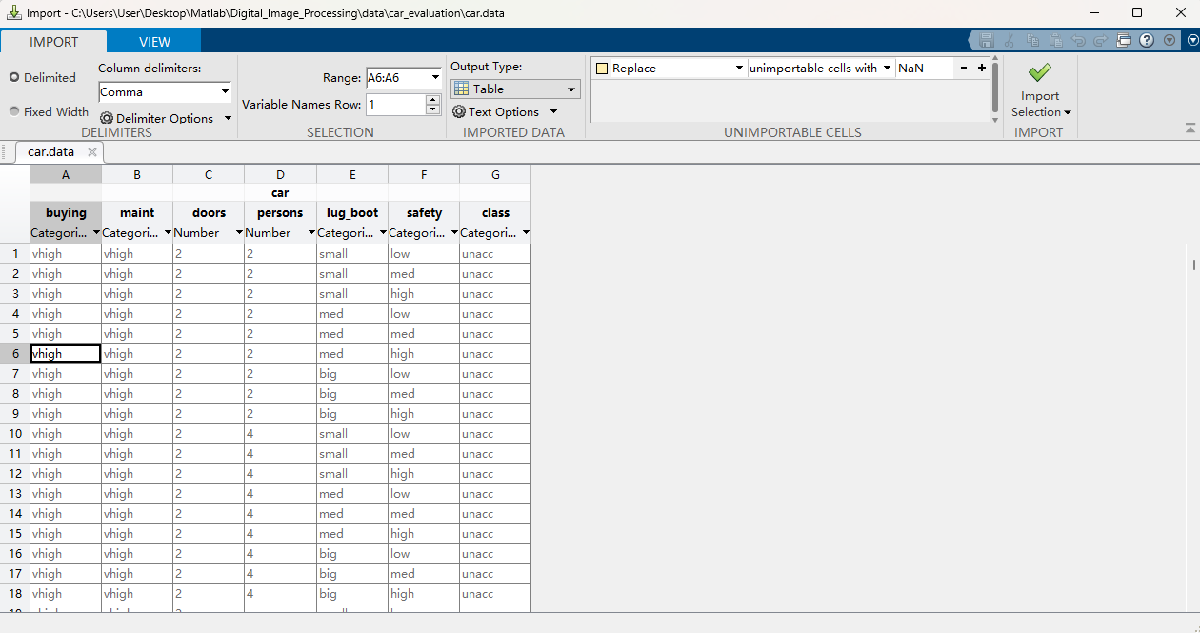

## Clear temporary variables

clear opts

## Data preprocessing

categorical_columns = ["buying", "maint", "lug_boot", "safety"];
data = car;
encoded_data = [];

for col = categorical_columns
    T = table(onehotencode(data{:, col}, 2));
    T = renamevars(T, "Var1", col);
    encoded_data = [encoded_data double(table2array(T))];
end

encoded_data

encoded_data =      0     0     0     1     0     0     0     1     0     0     1     0     1     0
     0     0     0     1     0     0     0     1     0     0     1     0     0     1
     0     0     0     1     0     0     0     1     0     0     1     1     0     0
     0     0     0     1     0     0     0     1     0     1     0     0     1     0
     0     0     0     1     0     0     0     1     0     1     0     0     0     1
     0     0     0     1     0     0     0     1     0     1     0     1     0     0
     0     0     0     1     0     0     0     1     1     0     0     0     1     0
     0     0     0     1     0     0     0     1     1     0     0     0     0     1
     0     0     0     1     0     0     0     1     1     0     0     1     0     0
     0     0     0     1     0     0     0     1     0     0     1     0     1     0



predicator = [encoded_data double(data.doors) double(data.persons)];
predicator = fillmissing2(predicator, 'nearest')'

predicator =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1

response = onehotencode(data.class, 2)'

response =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

## Training

nprtool

### Layer size = 10 (default)

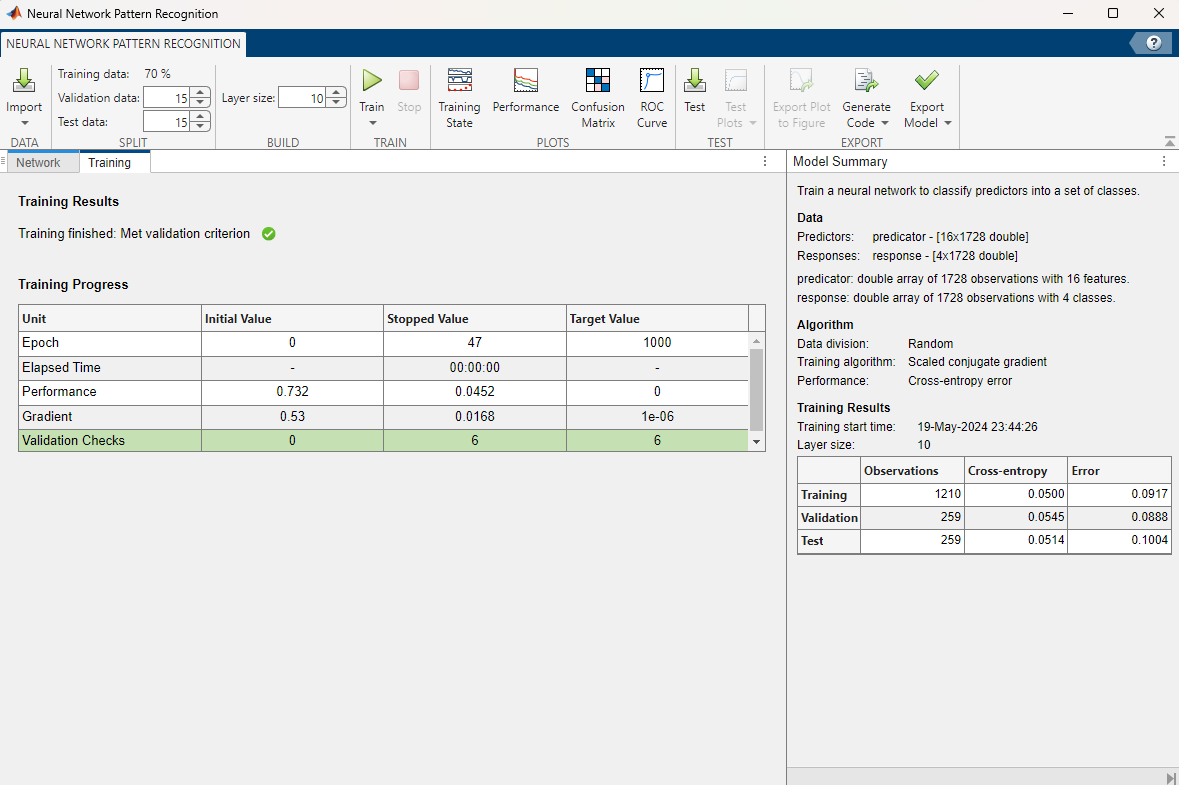

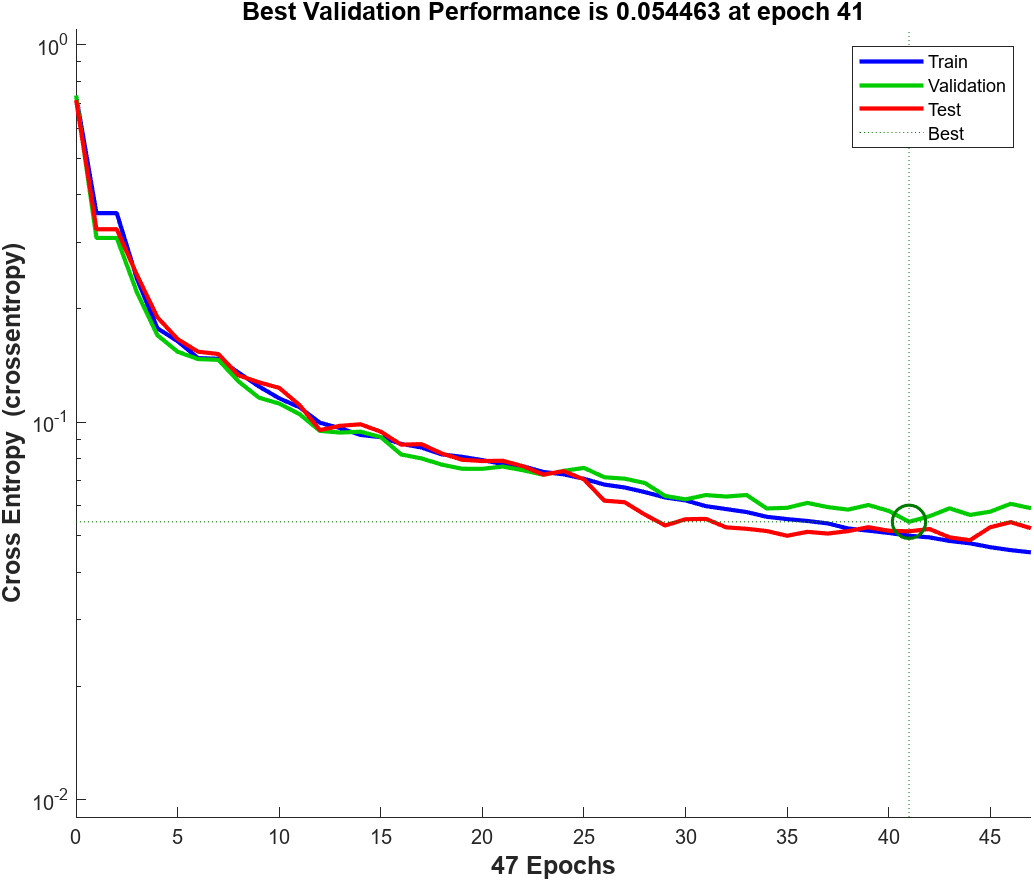

### Layer size = 5

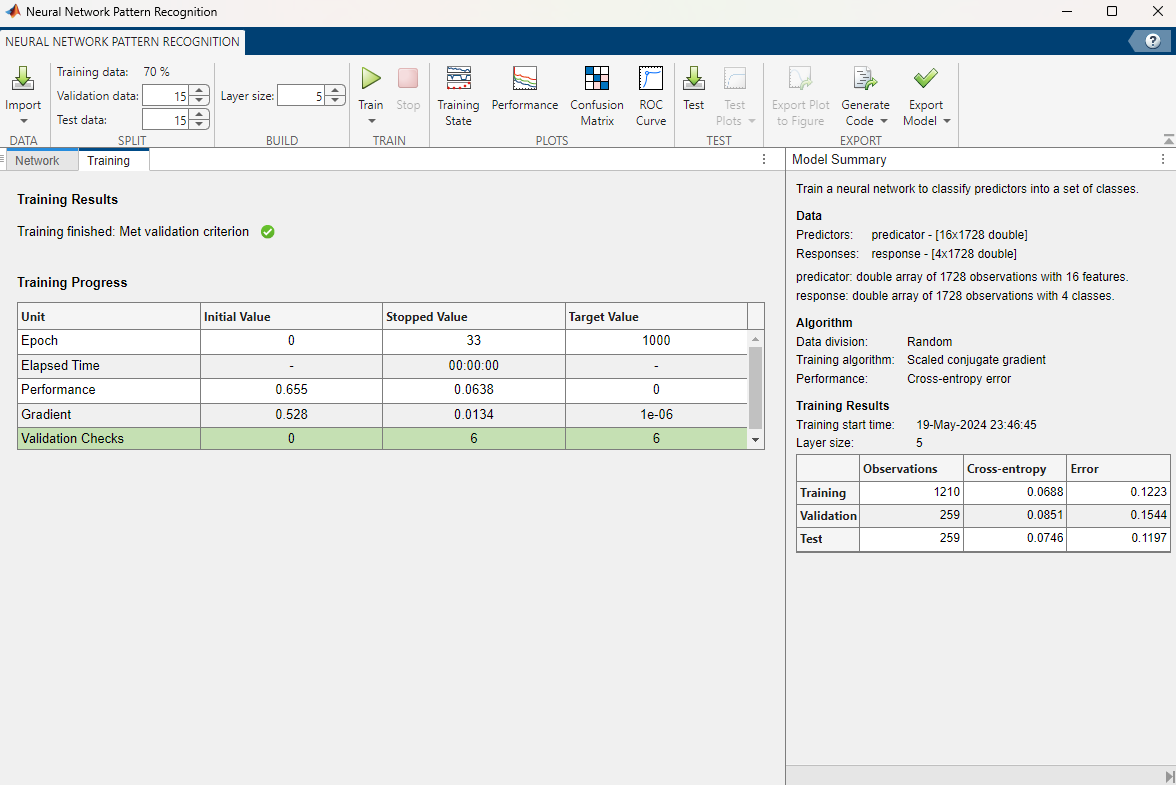

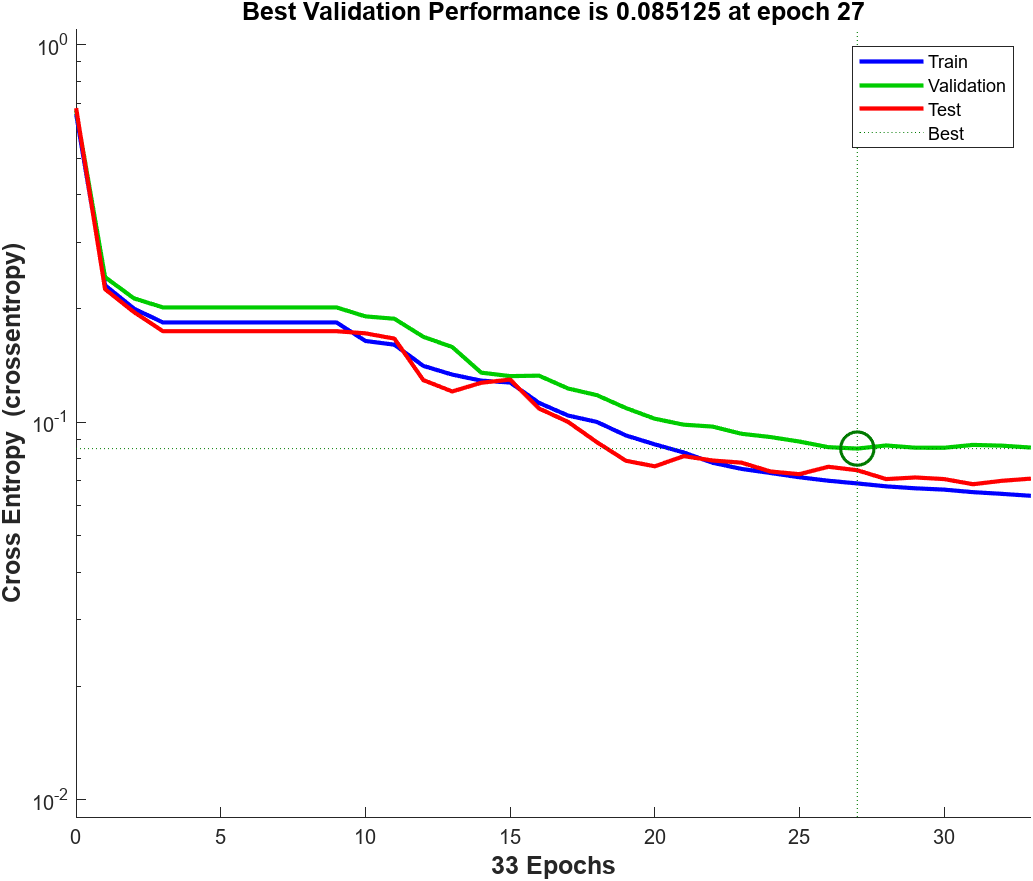

### Layer size = 20

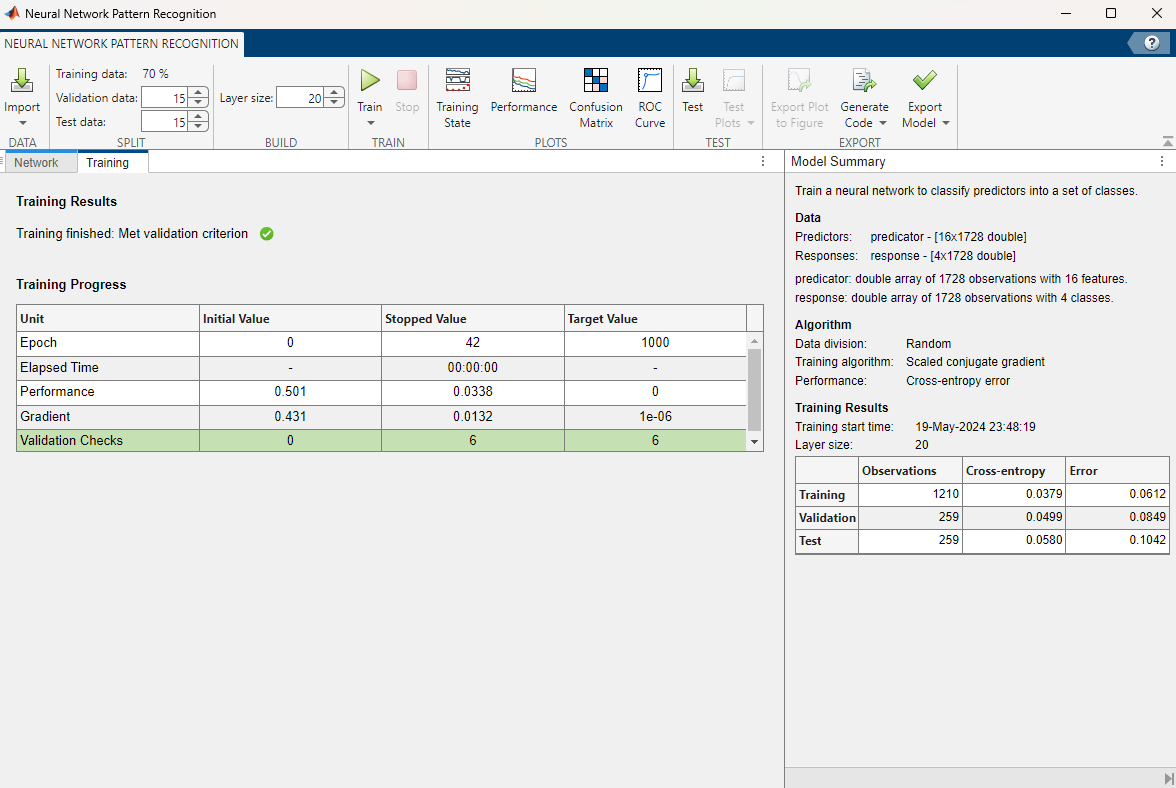\

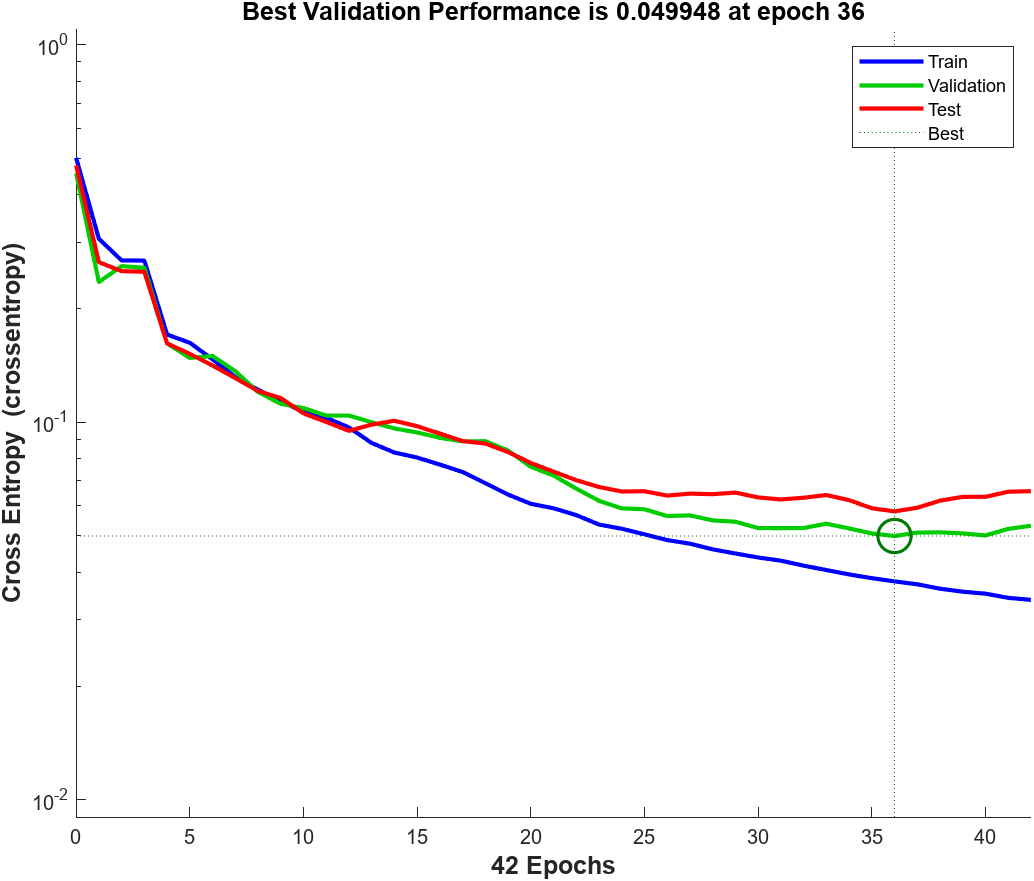

### More adjust